[y, f] = audioread('MUHA.wav');

dt = 1 / f;
T = length(y) * dt;
t = 0 : dt : T - dt;

V = 1 / dt;
dv = 1 / T;
v = -V/2 : dv : V/2;

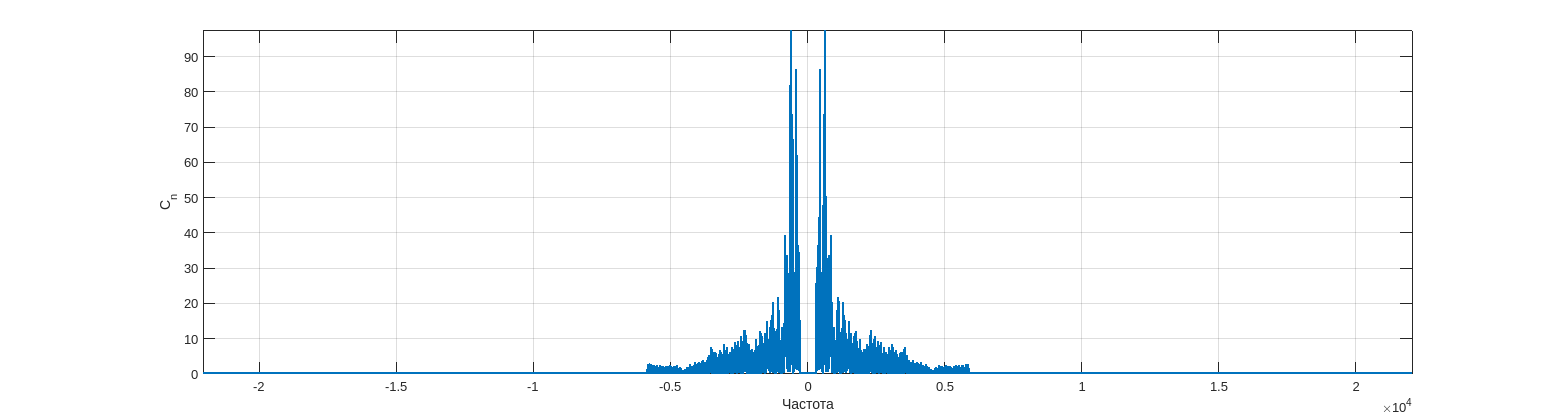

y_fourier = fftshift(fft(y));

v_0_offset = 1700;
v_0_left = fix(length(v) / 2) - v_0_offset;
v_0_right = fix(length(v) / 2) + v_0_offset;

y_fourier_filtered = zeros(size(y_fourier));
y_fourier_filtered(1:v_0_left) = y_fourier(1:v_0_left);
y_fourier_filtered(v_0_right:end) = y_fourier(v_0_right:end);

v_0_offset = 33000;
v_0_left = fix(length(v) / 2) - v_0_offset;
v_0_right = fix(length(v) / 2) + v_0_offset;

y_fourier_filtered(1:v_0_left) = 0;
y_fourier_filtered(v_0_right:end) = 0;

plot(v(1:end - 1), abs(y_fourier_filtered), 'LineWidth', 2);
axis('tight');
grid on;
xlabel("Частота");
ylabel("С_n");

pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-1000 0 1000 0]);

y_filtered = real(ifft(ifftshift(y_fourier_filtered)));

sound(y_filtered, f);